f = @(x) sin( exp(x+1) );
exact_value = cos(exp(1))*exp(1);

We'll run both formulas in parallel for a sequence of $h$ values.

h = 4.^(-1:-1:-8)';
FD1 = 0*h;  FD2 = 0*h;
for k = 1:length(h)
    FD1(k) = (f(h(k)) - f(0)) / h(k);
    FD2(k) = (f(h(k)) - f(-h(k))) / (2*h(k));
end

In each case $h$ is decreased by a factor of 4, so that the error is reduced by a factor of 4 in the first-order method and 16 in the second-order method.

error_FD1 = exact_value-FD1;  
error_FD2 = exact_value-FD2;
table(h,error_FD1,error_FD2)

ans = 8×3 table
        h         error_FD1      error_FD2 
    __________    __________    ___________

          0.25       0.53167      -0.085897
        0.0625       0.16675     -0.0044438
      0.015625      0.042784    -0.00027403
     0.0039062      0.010751    -1.7112e-05
    0.00097656     0.0026911    -1.0695e-06
    0.00024414    0.00067298    -6.6841e-08
    6.1035e-05    0.00016826    -4.1767e-09
    1.5259e-05    4.2065e-05    -2.7269e-10


A graphical comparison can be clearer. On a log-log scale, the error should (roughly) be a straight line whose slope is the order of accuracy. However, it's conventional in convergence plots, to show $h$ *decreasing* from left to right, which negates the slopes.

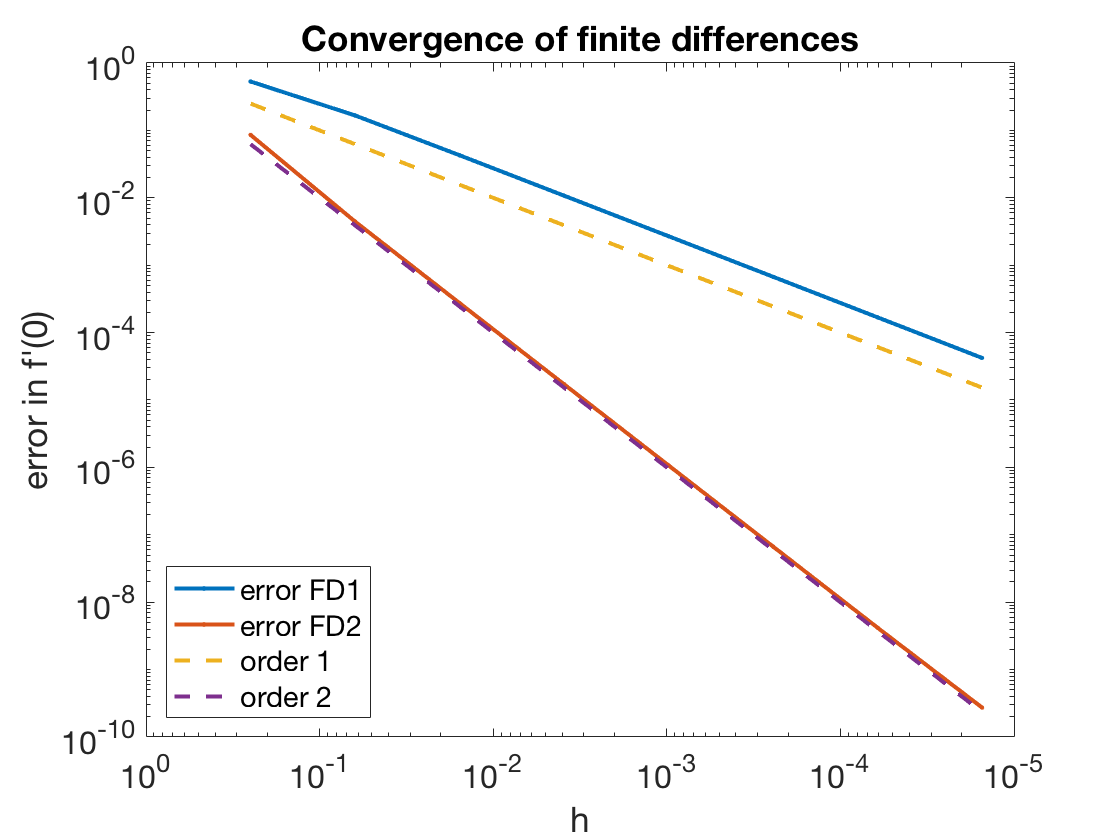

loglog(h,[abs(error_FD1),abs(error_FD2)],'.-')
hold on, loglog(h,[h,h.^2],'--')      % perfect 1st and 2nd order 
set(gca,'xdir','reverse')
xlabel('h'), ylabel('error in f''(0)')     % ignore this line
legend('error FD1','error FD2','order 1','order 2','location','southwest') % ignore this line
title('Convergence of finite differences')   % ignore this line